# 변경사항

## 2022.08.02

- 파일 읽어오기 전에 `clear all` 추가

- xlsx 파일 불러올 때 xVector와 xResampled 섞어서 표기한 것 수정

# 설치해야 하는 toolbox:

- signal processing toolbox

- image processing toolbox

# 1.파일 읽어오기

smr이든 xlsx든, 파일을 불러온 다음에 tVector와 xVector, sampleRateUsed 등 필요한 정보를 뽑아낸 다음에는

두 파일 유형 모두 다 똑같은 절차를 따라서 제가 만든 channel object로 변환합니다.

# 1.1. smr 파일 읽어오기

smrReader 패키지를 path에 추가해야 합니다. 

Spike-smr-reader-master/smrReader 로 끝나는 경로를 아래 함수에 인수로 입력해 주면 됩니다.

현재는 제 컴퓨터 기준으로 되어 있습니다.

clear all

addpath('/Users/mac/GitHub/neurosignal-matlab/severance/Spike-smr-reader-master/smrReader')

아래 코드는 폴더 선택 대화 상자를  열고, smr 파일들이 들어 있는 폴더를 선택합니다.

target_dir = uigetdir('', 'Select the target folder'); %

아래 코드는 선택한 폴더 내에 있는 모든 smr 파일을 가져와서 mat 파일(matlab에서 함수나 변수를 저장하는 파일)로 변환하고 같은 폴더 안에 저장합니다.

 
smr_list = [ dir(fullfile(target_dir, '*.smr'));
              ];
         
% Iterating the img_list
 
for i=1:length(smr_list)
    smr_list(i)
    fid=fopen(fullfile(target_dir, smr_list(i).name));
    SONImport(fid);
end

ans = 다음 필드를 포함한 struct :
       name: '210908_022.smr'
     folder: '/Users/mac/GitHub/neurosignal-matlab/data'
       date: '18-Jul-2022 12:53:39'
      bytes: 3052544
      isdir: 0
    datenum: 7.3872e+05


clear fid

위 코드를 실행하고 나서 폴더로 가 보면 .mat 파일이 생성된 것을 볼 수 있습니다. 파일 이름을 복사해 옵니다.

mat파일을 읽어옵니다. 채널별로 chanx와 headx 오브젝트가 생성됩니다. chanx에 데이터가 들어 있고, headx에 관련 정보가 들어 있습니다.

load(target_dir+"/210908_022.mat")

파일 하나당 FileInfo

필요한 정보를 뽑아냅니다. 

아래부터의 작업은 채널 하나에 적용되는 내용입니다. 여러 개의 채널로 작업할 경우, 각 채널마다 아래의 작업을 해 주시면 됩니다. 즉, 아래의 코드를 복사하고 chan1을 chan2로 바꾸는 식으로 하시면 됩니다.

start = head1.start; %시작 시간
stop = head1.stop; %종료 시간

%관측치 개수
nTimestamps = size(chan1); 
nTimestamps = nTimestamps(1);

%sampling rate 계산, 25000과 일치하는 것 확인.
sampleRateUsed = (nTimestamps-1)/(stop-start);

xVector = chan1; %시그널 벡터 생성

increment = (stop - start)/(nTimestamps-1); %관측치와 관측치 사이 시간 거리 계싼
tVector = start:increment:stop; %시간 벡터 생성




이제 시그널 벡터와 시간 벡터를 가지고 채널 오브젝트를 생성합니다. 

그래프 여러 개 그리는 것을 시연하기 위해, 똑같은 채널에 채널2라 이름 붙였습니다. 채널이 여러개 있을 때는 이렇게 할 필요가 없이 원래 있는 여러 개의 채널을 쓰면 됩니다.




                 % 마지막 3개는 단순히 관리를 위한 번호: organoid number, channel number, month number
channel_1 = channel(xVector, tVector, sampleRateUsed, 1, 1, 1);

channel number = 1
sampling rate = 25000.000000Hz
starts at 0.000000, ends at 60.714560, duration = 60.714560
number of timestamps = 1517865



channel_2 = channel(xVector, tVector, sampleRateUsed, 1, 2, 1); %그래프 여러 개 그리는 것을 시연하기 위해, 똑같은 채널에 채널2라 이름 붙임

channel number = 2
sampling rate = 25000.000000Hz
starts at 0.000000, ends at 60.714560, duration = 60.714560
number of timestamps = 1517865



각 채널의 10초에서 40초 구간만 가져옵니다.

channel_1.cutTime([10,40])

Reset all preprocessing of signalsnew startTime = 9.999960
new endTime = 40.000040
new duration = 30.000080
new nTimestamp = 750003


channel_2.cutTime([10,40])

Reset all preprocessing of signalsnew startTime = 9.999960
new endTime = 40.000040
new duration = 30.000080
new nTimestamp = 750003


반복문을 이용해 그래프를 편하게 그리기 위해, 채널들을 묶습니다. 

모든 채널들이 시간 정보는 같으므로, 공통된 t 벡터를 사용하기로 합니다.

channels = [1,2]; % 채널 번호 목록. 1번 , 3번, 4번 채널이 있으면 [1,3,4]라 하면 됩니다.
rawSignalBundle = struct("rawsignal", {channel_1.raw, channel_2.raw});
common_t = channel_1.t;

# 1.2. xlsx파일 읽어오기

파일을 읽어옵니다.

clear all
raw_data = readmatrix("/Users/mac/GitHub/neurosignal-matlab/data/210908_022.xlsx"); %문종민의 컴퓨터에서 작업할 때

필요한 정보를 뽑아냅니다.

size_of_data = size(raw_data) % 데이터 행과 열 개수

size_of_data =       750002           3


number_of_timestamp = size_of_data(1)-1 % 열 개수 - 1 = 측정 timestamp 개수

number_of_timestamp = 750001

여기서 주의할 점은 엑셀 파일은 실제로는 10초-30초 구간인데 파일에는 0초-30초로 기록되어 있으므로 10을 더해 주어야 실제 시간이 나온다는 것입니다.

%시간 벡터 저장 및 sampling frequency 계산
tVector = raw_data(2:end,1); %시간 벡터를 따로 저장. 첫 번째 원소는 컬럼 이름이므로 제외
tVector = tVector + 10 ;
sampleRateUsed = (number_of_timestamp-1)/(tVector(end) - tVector(1)) %sample rate 계산. 전체 시간을 관측치 개수로 나눔

sampleRateUsed = 25000

size(tVector)

ans =       750001           1




xVector = raw_data(2:end,3); % time 열에 맞춰 데이터를 불러오기 때문에, 빈칸이 NaN으로 들어올 수 있습니다. 이 부분을 제거해 줍니다.
size(xVector)

ans =       750001           1



                 % 마지막 3개는 단순히 관리를 위한 번호: organoid number, channel number, month number
channel_1 = channel(xVector, tVector, sampleRateUsed, 1, 1, 1);

channel number = 1
sampling rate = 25000.000000Hz
starts at 10.000000, ends at 40.000000, duration = 30.000000
number of timestamps = 750001



channel_2 = channel(xVector, tVector, sampleRateUsed, 1, 2, 1); %그래프 여러 개 그리는 것을 시연하기 위해, 똑같은 채널에 채널2라 이름 붙임

channel number = 2
sampling rate = 25000.000000Hz
starts at 10.000000, ends at 40.000000, duration = 30.000000
number of timestamps = 750001



channels = [1,2]; % 채널 번호 목록. 1번 , 3번, 4번 채널이 있으면 [1,3,4]라 하면 됩니다.

반복문을 이용해 그래프를 편하게 그리기 위해, 채널들을 묶습니다. 

모든 채널들이 시간 정보는 같으므로, 공통된 t 벡터를 사용하기로 합니다.


rawSignalBundle = struct("rawsignal", {channel_1.raw, channel_2.raw});
common_t = channel_1.t;

# 2. 플롯 그리기

플롯 그리는 코드들은 위에서 만든 rawSignalBundle에 대한 반복문을 사용하기 때문에, 위에서 작업에 필요한 channel을 다 추가했다면 아래 코드에서 바꿀 내용이 별로 없습니다.

channel 개수에 따라 subplot 배열 정도만 바꿔 주면 됩니다. 해당하는 부분의 코드에 %%%%%%로 감싸서 표시를 해 두었습니다.

## 1.raw signal



figure;
set(0,'defaultfigurepos',[2000 500 1000 400])
for i=1:length(rawSignalBundle)
    channelNum = channels(i) %채널 목록의 i번째 원소가 채널 번호이다.

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    subplot(2,1,i); %2 * 1 크기의 타일에 서브플롯들을 그린다.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    plot(common_t, rawSignalBundle(i).rawsignal);  %rawSignalBundle이라는 struct에서 i번째 원소를 가져오고, 거기서 "rawsignal"이라는 항목으로 저장된 데이터를 가져온다.
    title("channel "+channelNum)
end

channelNum = 1

channelNum = 2

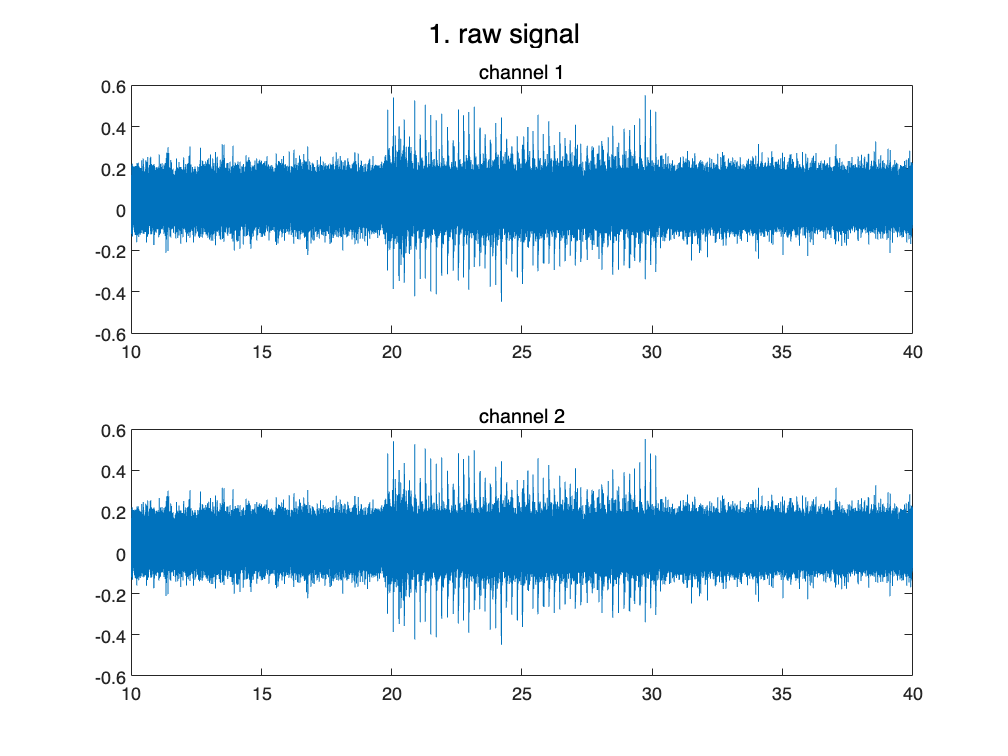

sgtitle('1. raw signal')

## 2.filtered signal

Fs = sampleRateUsed %sampling frequency. 앞에서 계산함.

Fs = 25000

보내 주신 참고 코드를 따라서, nth order butterworth filtering을 진행합니다.

3rd order 이상으로 올리면 NaN이 나와서 2nd order로 하였습니다.

   % Trec = 60;
   % Sampling interval, frequency 
    %timeline = t_amplifier;

    % Filtering (band pass filter for spike counting)
for i=1:length(rawSignalBundle)
    channelNum = channels(i);
    rawSignalNow = double(rawSignalBundle(i).rawsignal); %i번째 raw signal

    %filtering 수행. 0을 넣으면 안되므로 0.01을 넣음
    n=2; 
    Wn=[0.01 300]; % band pass filter range [0,300]. sample code의 order 7로 하면 NaN이 나옴.
    [b, a] = butter(n, Wn/(Fs/2), 'bandpass'); 
    
    bpf_data(i,:) = filtfilt(b,a,rawSignalNow); %필터링한 데이터가 저장되는 행렬
   
end

figure; 
for i=1:size(bpf_data,1)    
        channelNum = channels(i)

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    subplot(2, 1, i); %서브플롯 타일(혹은 그리드) 사이즈. 여기만 채널 개수에 맞게 바꿔주시면 됩니다.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    plot(common_t, bpf_data(i,:))


        title("channel "+channelNum)

    %font 
    set(gca, 'FontSize',12)
     xlabel('time(s)','FontSize',10), ylabel('frequency(Hz)','FontSize',10)
end

channelNum = 1

channelNum = 2

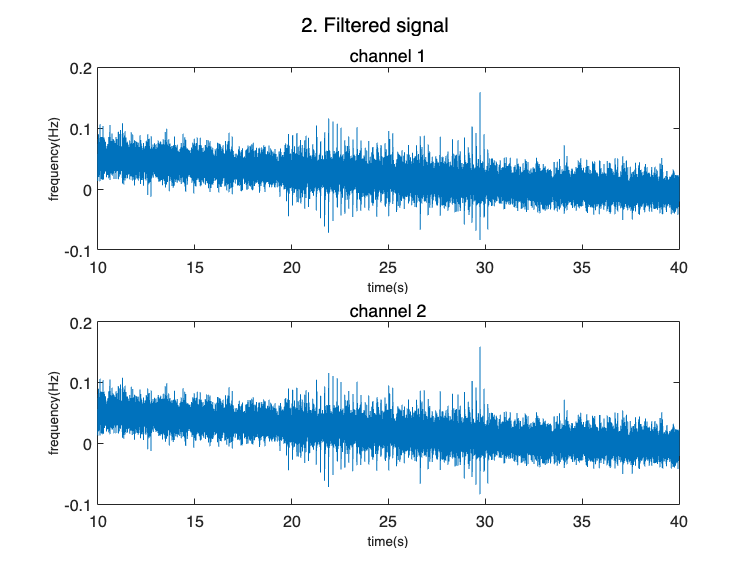

sgtitle('2. Filtered signal')

## 3. SFTF

채널 개수만큼 자동으로  blurred_save_n이 생성되고, 이 객체가 나중에 gamma, beta 등 밴드의 그래프를 그릴 때 사용됨

모든 변수(trec, fc 등)은 보내주신 참고 코드와 같은 값을 사용했습니다.

아랫부분의 서브플롯 배치 정하는 부분 코드만 채널 개수에 맞게 바꿔주시면 됩니다. subplot(2,1,i)는 2*1모양 그리드에서 i번째 자리에 이번 subplot을 그리겠다는 의미입니다.

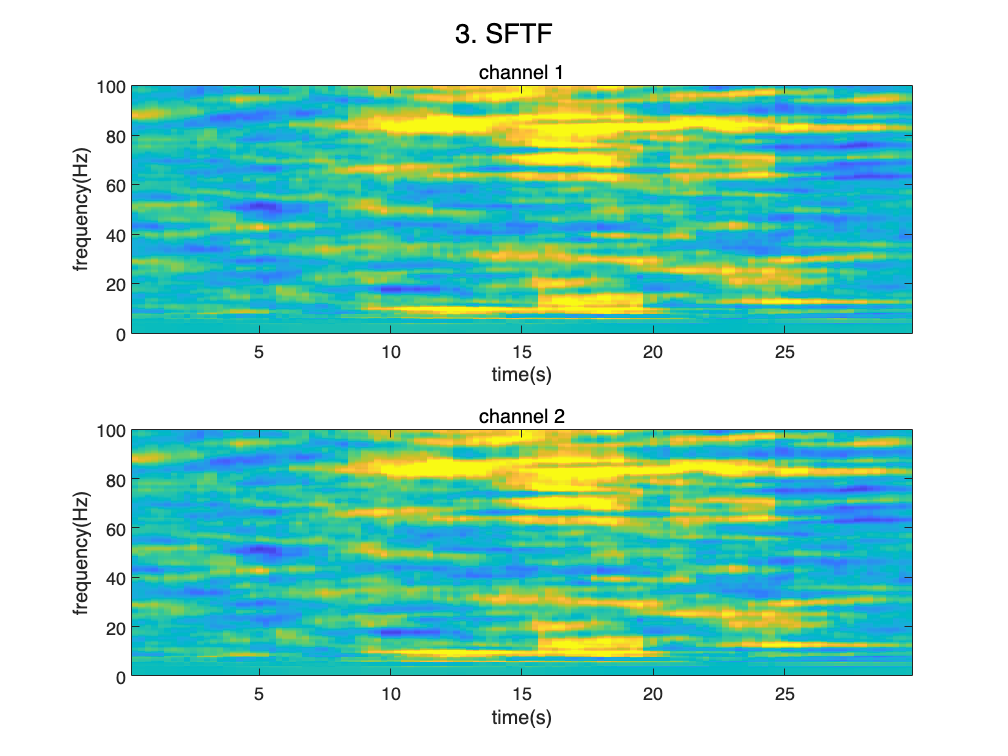



Trec = 60;
%% LFP
figure;
for i=1:length(rawSignalBundle)
    channelNum = channels(i);
    rawSignalNow = double(rawSignalBundle(i).rawsignal);
        
    % Filtering (low pass filter for LFP)
        Fc = 300; %300
        [b,a] = butter(4,Fc/(Fs/2),'low');
        lpf_data= filtfilt(b,a,rawSignalNow);
        clear a b
        
        % Desampling 1000 Hz
        dFs = 1000;
        lpf_data_de= resample(lpf_data,dFs,Fs);
        x_de= 1/dFs:1/dFs:length(lpf_data_de)/dFs;
        
        % STFT 생성
        R= 500; %500                 % welch window size=  1초
        noverlap = R/2;          % 50 % overlap (1.25로 나누면 좀더 촘촘해짐, 2)
        window1= hanning(R);
        NFFT =2048*4;              %2^nextpow2(L);
        [S, F, T]= spectrogram(lpf_data_de, window1, noverlap, NFFT, dFs);
        %     clear R window1 noverlap NFFT
        %                     figure(), clf
        %                     colorbar = [0 2000];    % color map을 조절하며 원하는 scale 찾음
        %                     imagesc(T,F,abs(S),colorbar);
        %                     axis xy
        %                     xlabel('time(s)'), ylabel('frequency(Hz)'), title('');
        %                     ylim([0 Fc]), xlim([1 Trec])
        %
        % Normalized STFT
        before_fin = floor(double(length(T)*(20/Trec)));
        before_stft = abs(S(:,1:before_fin));
        during_after_stft= abs(S(:,1:end));
        
        baseline_value= mean(before_stft,2);
        mul= ones(1,length(T));
        baseline_matrix= baseline_value*mul;
        
        % Normalizaed: (X-baseline)/baseline
        normalized_stft= (during_after_stft-baseline_matrix)./baseline_matrix;
        
        %     figure(), \%clf




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%% Plotting part %%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        subplot(2,1,i)%%%% 여기만 채널 수에 맞게 바꿔주시면 됩니다.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        colorbar= [0 1];
%         imagesc((T(1:end)),F,normalized_stft,colorbar);%
%         axis xy
%         xlabel('time(s)'), ylabel('frequency(Hz)'),
%         ylim([0 100])
        
        PSF = fspecial('average',[2 16]);
        Blurred_n = imfilter(normalized_stft,PSF,'conv');
                
        imagesc((T(1:end)),F,Blurred_n,[-0.5 0.5]); ylim([0 100])
        axis xy
         xlabel('time(s)'), ylabel('frequency(Hz)'),
%         clear PSF Blurred_n lpf_data lpf_data_de;

        Blurred_save(i,:,:)=Blurred_n;
        title("channel "+channelNum)
end
sgtitle('3. SFTF')

    
    clear Blurred_n

## 4. gamma, beta, alpha, theta, delta

Wn2= find(F>25&F<50)가 아니라 Wn2= find(F>25&F<100)이어야 하는 것 아닌지?

### 4.1. gamma

채널 개수만큼 그림을 만듭니다.. 앞에서 만든 blurred_save 객체를 그대로 사용합니다.

여기서는 반복문을 쓰지 않으므로 채널 개수에 맞게 %로 코멘트 처리를 해 주면 됩니다.

지난 단계에서 만든 데이터를 그대로 사용하므로, 코드 아랫 부분에 서브플롯 배치에 관한 부분만 알맞게 수정해 주면 됩니다. 다른 부분은 건드릴 필요가 없습니다.

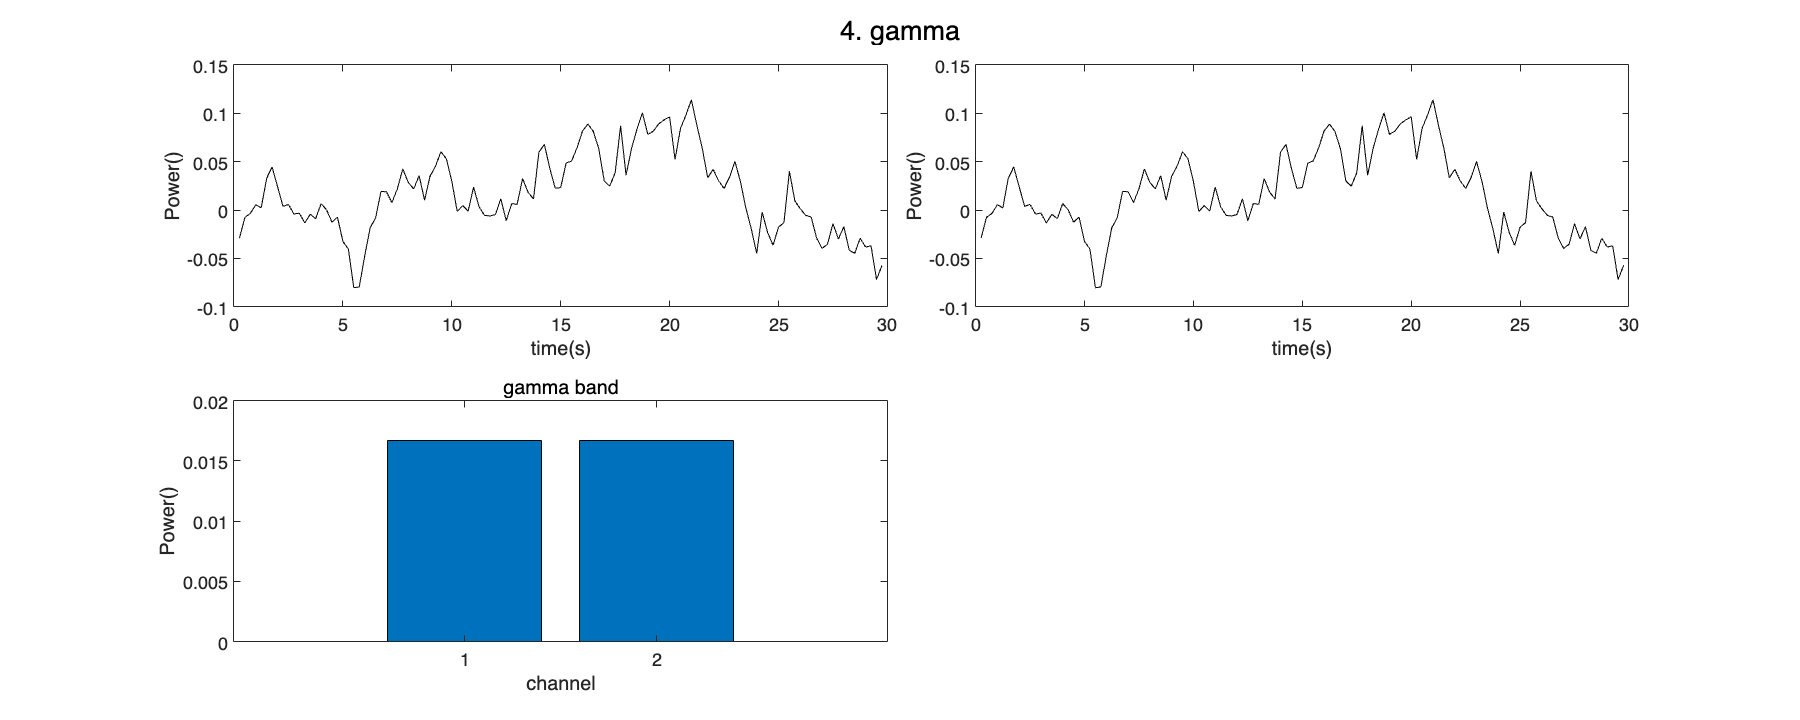

%% power-time plot
% a (8 ~ 13 hz)
% b (12 ~ 33 hz)
% theta (3.5 ~ 8 hz)
% delta (1 ~ 3 hz)
% gamma (25~100 hz)

% Frequency 12-33 Hz
gamma_power =[];
Wn2= find(F>25&F<50); %
Blurred_1(:,:)=Blurred_save(1,:,:);
Blurred_2(:,:)=Blurred_save(2,:,:);
%Blurred_3(:,:)=Blurred_save(3,:,:);
%Blurred_4(:,:)=Blurred_save(4,:,:);
%Blurred_5(:,:)=Blurred_save(5,:,:);
%Blurred_6(:,:)=Blurred_save(6,:,:);
%Blurred_7(:,:)=Blurred_save(7,:,:);

gamma_power_1=mean(Blurred_1(Wn2,:));
gamma_power_2=mean(Blurred_2(Wn2,:));
%gamma_power_3=mean(Blurred_3(Wn2,:));
%gamma_power_4=mean(Blurred_4(Wn2,:));
%gamma_power_5=mean(Blurred_5(Wn2,:));
%gamma_power_6=mean(Blurred_6(Wn2,:));
%gamma_power_7=mean(Blurred_7(Wn2,:));

gamma_power(1) = mean(gamma_power_1);
gamma_power(2) = mean(gamma_power_2);
%gamma_power(3) = mean(gamma_power_3);
%gamma_power(4) = mean(gamma_power_4);
%gamma_power(5) = mean(gamma_power_5);
%gamma_power(6) = mean(gamma_power_6);
%gamma_power(7) = mean(gamma_power_7);

figure;

%2 * 4 타일을 만든 다음, 한 그래프가 가로로 두 개의 자리를 차지하게 함
% 자리배치:
% 1 2 3 4
% 5 6 7 8

%플롯 자리 정하는 부분만 채널의 개수와 원하는 배치에 맞게 바꿔 주시면 됩니다.
subplot(2,4,[1 2]),plot(T,gamma_power_1,'k');   % 1,2번째 칸 차지
xlabel('time(s)'), ylabel('Power()')
subplot(2,4,[3 4]),plot(T,gamma_power_2,'k');   % 3,4번째 칸 차지
xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[5 6]),plot(T,gamma_power_3,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[7 8]),plot(T,gamma_power_4,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[9 10]),plot(T,gamma_power_5,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[11 12]),plot(T,gamma_power_6,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[13 14]),plot(T,gamma_power_7,'k');
%xlabel('time(s)'), ylabel('Power()')

subplot(2,4,[5 6]),bar(gamma_power);
xlabel('channel'), ylabel('Power()');
%ylim([0 0.05]) % y 범위 적절히 조절

subtitle('gamma band')

sgtitle('4. gamma')

### 4.2. beta

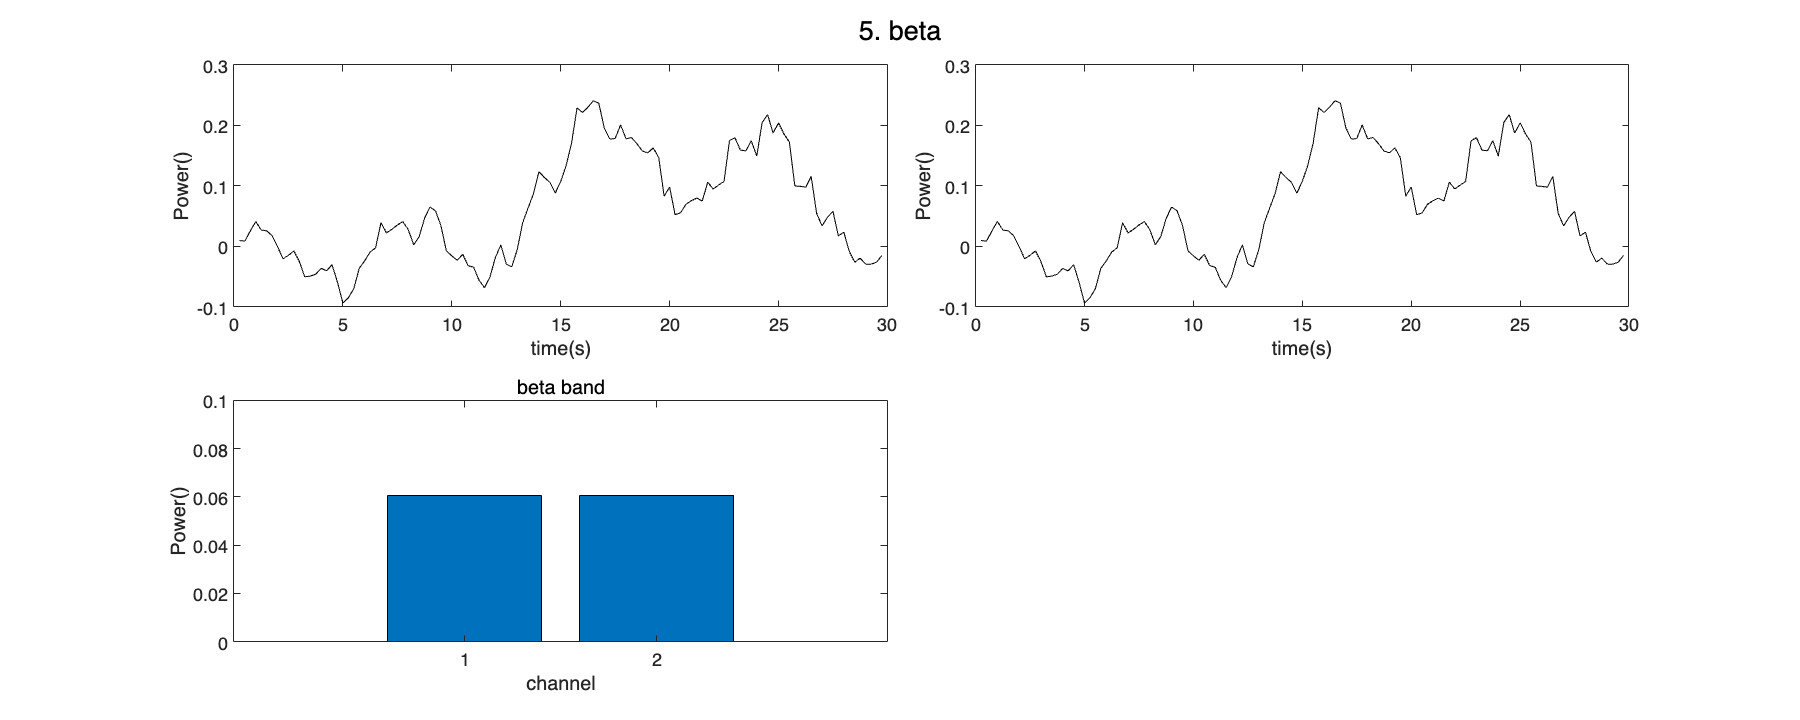

% Frequency 3.5-8 Hz
Wn3= find(F>12&F<33);
Alpha_power =[];
Blurred_1(:,:)=Blurred_save(1,:,:);
Blurred_2(:,:)=Blurred_save(2,:,:);
%Blurred_3(:,:)=Blurred_save(3,:,:);
%Blurred_4(:,:)=Blurred_save(4,:,:);
%Blurred_5(:,:)=Blurred_save(5,:,:);
%Blurred_6(:,:)=Blurred_save(6,:,:);
%Blurred_7(:,:)=Blurred_save(7,:,:);

Beta_power_1=mean(Blurred_1(Wn3,:));
Beta_power_2=mean(Blurred_2(Wn3,:));
%Beta_power_3=mean(Blurred_3(Wn3,:));
%Beta_power_4=mean(Blurred_4(Wn3,:));
%Beta_power_5=mean(Blurred_5(Wn3,:));
%Beta_power_6=mean(Blurred_6(Wn3,:));
%Beta_power_7=mean(Blurred_7(Wn3,:));
Alpha_power(1) = mean(Beta_power_1);
Alpha_power(2) = mean(Beta_power_2);
%Beta_power(3) = mean(Beta_power_3);
%Beta_power(4) = mean(Beta_power_4);
%Beta_power(5) = mean(Beta_power_5);
%Beta_power(6) = mean(Beta_power_6);
%Beta_power(7) = mean(Beta_power_7);

figure;
%2 * 4 타일을 만든 다음, 한 그래프가 가로로 두 개의 자리를 차지하게 함
% 자리배치:
% 1 2 3 4
% 5 6 7 8

%플롯 자리 정하는 부분만 채널의 개수와 원하는 배치에 맞게 바꿔 주시면 됩니다.
subplot(2,4,[1 2]),plot(T,Beta_power_1,'k');
xlabel('time(s)'), ylabel('Power()')
subplot(2,4,[3 4]),plot(T,Beta_power_2,'k');
xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[5 6]),plot(T,Beta_power_3,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[7 8]),plot(T,Beta_power_4,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[9 10]),plot(T,Beta_power_5,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[11 12]),plot(T,Beta_power_6,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[13 14]),plot(T,Beta_power_7,'k');
%xlabel('time(s)'), ylabel('Power()')

subplot(2,4,[5 6]),bar(Alpha_power);
xlabel('channel'), ylabel('Power()');
%ylim([0 0.1]) % y 범위 적절히 조절
subtitle('beta band')
sgtitle('5. beta')

### 4.3. alpha

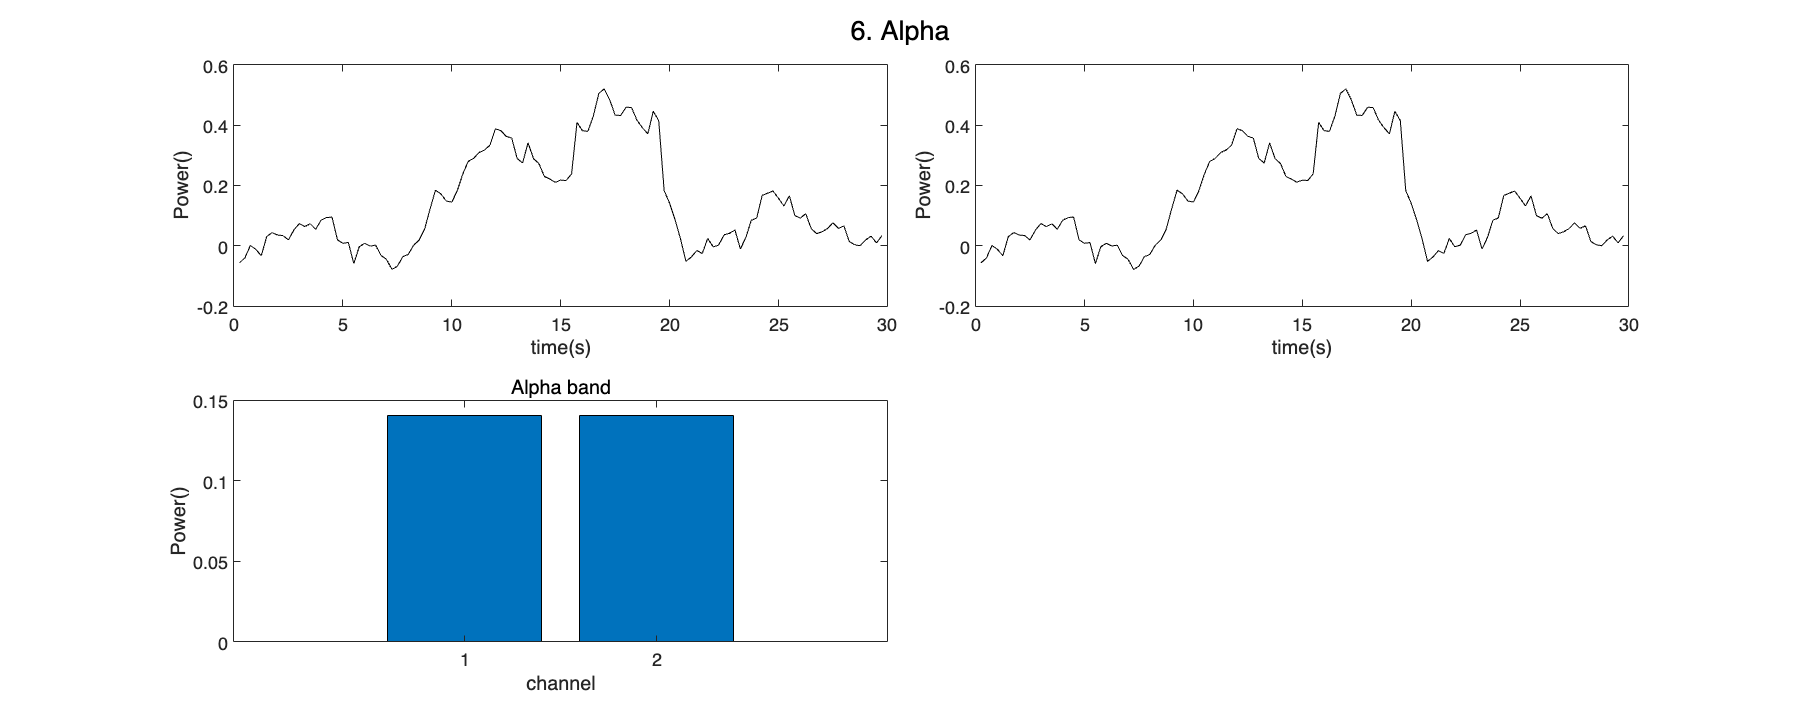

% Frequency 8-13 Hz
Wn3= find(F>8&F<13);
Alpha_power =[];
Blurred_1(:,:)=Blurred_save(1,:,:);
Blurred_2(:,:)=Blurred_save(2,:,:);
%Blurred_3(:,:)=Blurred_save(3,:,:);
%Blurred_4(:,:)=Blurred_save(4,:,:);
%Blurred_5(:,:)=Blurred_save(5,:,:);
%Blurred_6(:,:)=Blurred_save(6,:,:);
%Blurred_7(:,:)=Blurred_save(7,:,:);

Alpha_power_1=mean(Blurred_1(Wn3,:));
Alpha_power_2=mean(Blurred_2(Wn3,:));
%Alpha_power_3=mean(Blurred_3(Wn3,:));
%Alpha_power_4=mean(Blurred_4(Wn3,:));
%Alpha_power_5=mean(Blurred_5(Wn3,:));
%Alpha_power_6=mean(Blurred_6(Wn3,:));
%Alpha_power_7=mean(Blurred_7(Wn3,:));
Alpha_power(1) = mean(Alpha_power_1);
Alpha_power(2) = mean(Alpha_power_2);
%Alpha_power(3) = mean(Alpha_power_3);
%Alpha_power(4) = mean(Alpha_power_4);
%Alpha_power(5) = mean(Alpha_power_5);
%Alpha_power(6) = mean(Alpha_power_6);
%Alpha_power(7) = mean(Alpha_power_7);

figure;
%2 * 4 타일을 만든 다음, 한 그래프가 가로로 두 개의 자리를 차지하게 함
% 자리배치:
% 1 2 3 4
% 5 6 7 8

%플롯 자리 정하는 부분만 채널의 개수와 원하는 배치에 맞게 바꿔 주시면 됩니다.
subplot(2,4,[1 2]),plot(T,Alpha_power_1,'k');
xlabel('time(s)'), ylabel('Power()')
subplot(2,4,[3 4]),plot(T,Alpha_power_2,'k');
xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[5 6]),plot(T,Alpha_power_3,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[7 8]),plot(T,Alpha_power_4,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[9 10]),plot(T,Alpha_power_5,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[11 12]),plot(T,Alpha_power_6,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[13 14]),plot(T,Alpha_power_7,'k');
%xlabel('time(s)'), ylabel('Power()')

subplot(2,4,[5 6]),bar(Alpha_power);
xlabel('channel'), ylabel('Power()');
%ylim([0 0.15]) % y 범위 적절히 조절
subtitle('Alpha band')
sgtitle('6. Alpha')

### 4.4 theta

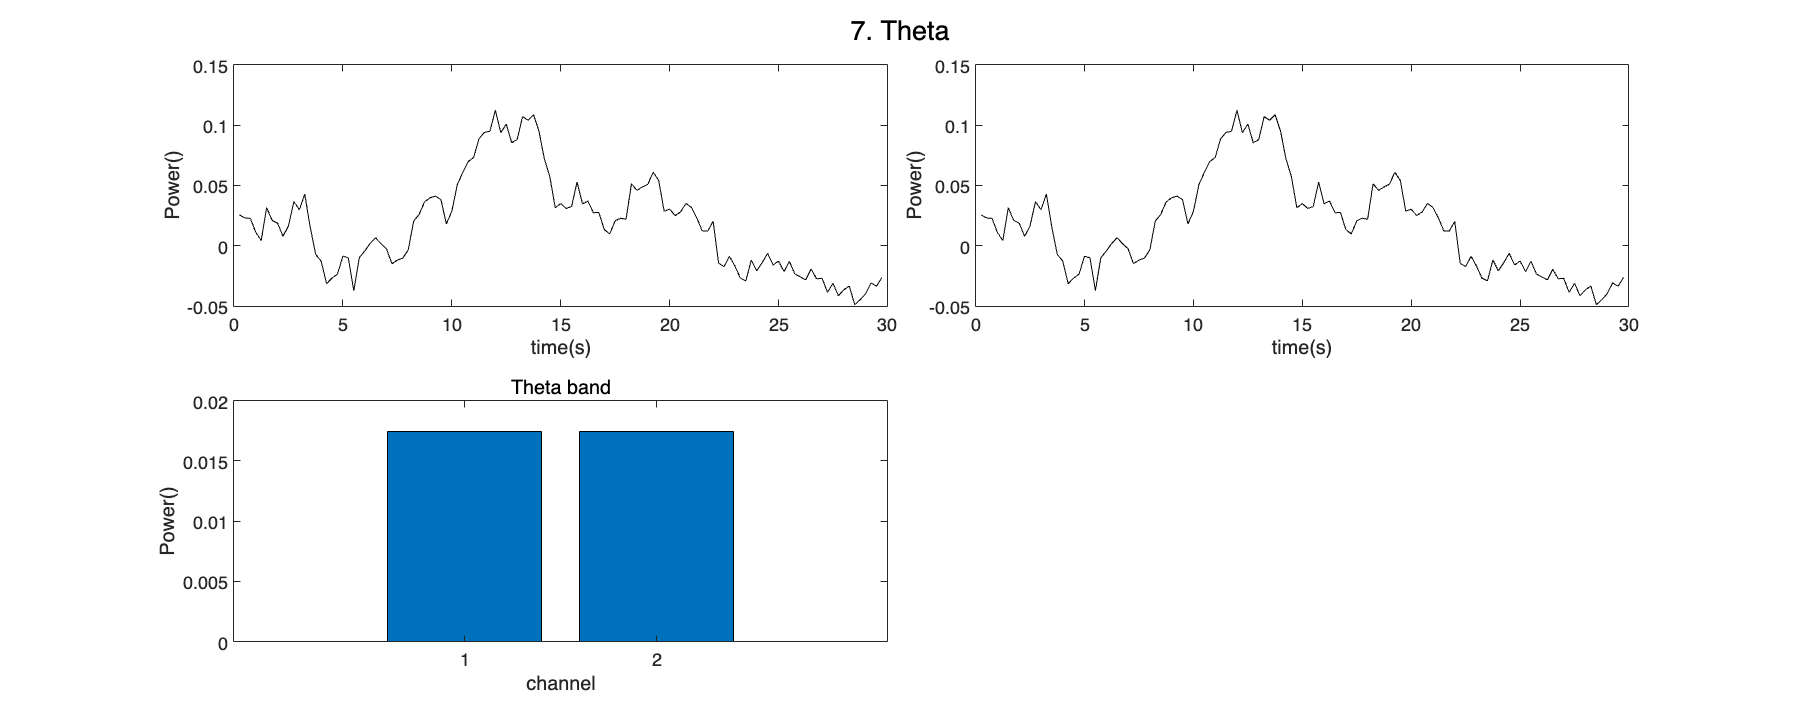

% Frequency 3.5-8 Hz
Wn3= find(F>3.5&F<8);
Theta_power =[];
Blurred_1(:,:)=Blurred_save(1,:,:);
Blurred_2(:,:)=Blurred_save(2,:,:);
%Blurred_3(:,:)=Blurred_save(3,:,:);
%Blurred_4(:,:)=Blurred_save(4,:,:);
%Blurred_5(:,:)=Blurred_save(5,:,:);
%Blurred_6(:,:)=Blurred_save(6,:,:);
%Blurred_7(:,:)=Blurred_save(7,:,:);

Theta_power_1=mean(Blurred_1(Wn3,:));
Theta_power_2=mean(Blurred_2(Wn3,:));
%Theta_power_3=mean(Blurred_3(Wn3,:));
%Theta_power_4=mean(Blurred_4(Wn3,:));
%Theta_power_5=mean(Blurred_5(Wn3,:));
%Theta_power_6=mean(Blurred_6(Wn3,:));
%Theta_power_7=mean(Blurred_7(Wn3,:));
Theta_power(1) = mean(Theta_power_1);
Theta_power(2) = mean(Theta_power_2);
%Theta_power(3) = mean(Theta_power_3);
%Theta_power(4) = mean(Theta_power_4);
%Theta_power(5) = mean(Theta_power_5);
%Theta_power(6) = mean(Theta_power_6);
%Theta_power(7) = mean(Theta_power_7);

figure;
%2 * 4 타일을 만든 다음, 한 그래프가 가로로 두 개의 자리를 차지하게 함
% 자리배치:
% 1 2 3 4
% 5 6 7 8

%플롯 자리 정하는 부분만 채널의 개수와 원하는 배치에 맞게 바꿔 주시면 됩니다.
subplot(2,4,[1 2]),plot(T,Theta_power_1,'k');
xlabel('time(s)'), ylabel('Power()')
subplot(2,4,[3 4]),plot(T,Theta_power_2,'k');
xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[5 6]),plot(T,Theta_power_3,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[7 8]),plot(T,Theta_power_4,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[9 10]),plot(T,Theta_power_5,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[11 12]),plot(T,Theta_power_6,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[13 14]),plot(T,Theta_power_7,'k');
%xlabel('time(s)'), ylabel('Power()')

subplot(2,4,[5 6]),bar(Theta_power);
xlabel('channel'), ylabel('Power()');
%ylim([0 0.15]) % y 범위 적절히 조절
subtitle('Theta band')
sgtitle('7. Theta')

### 4.5 delta

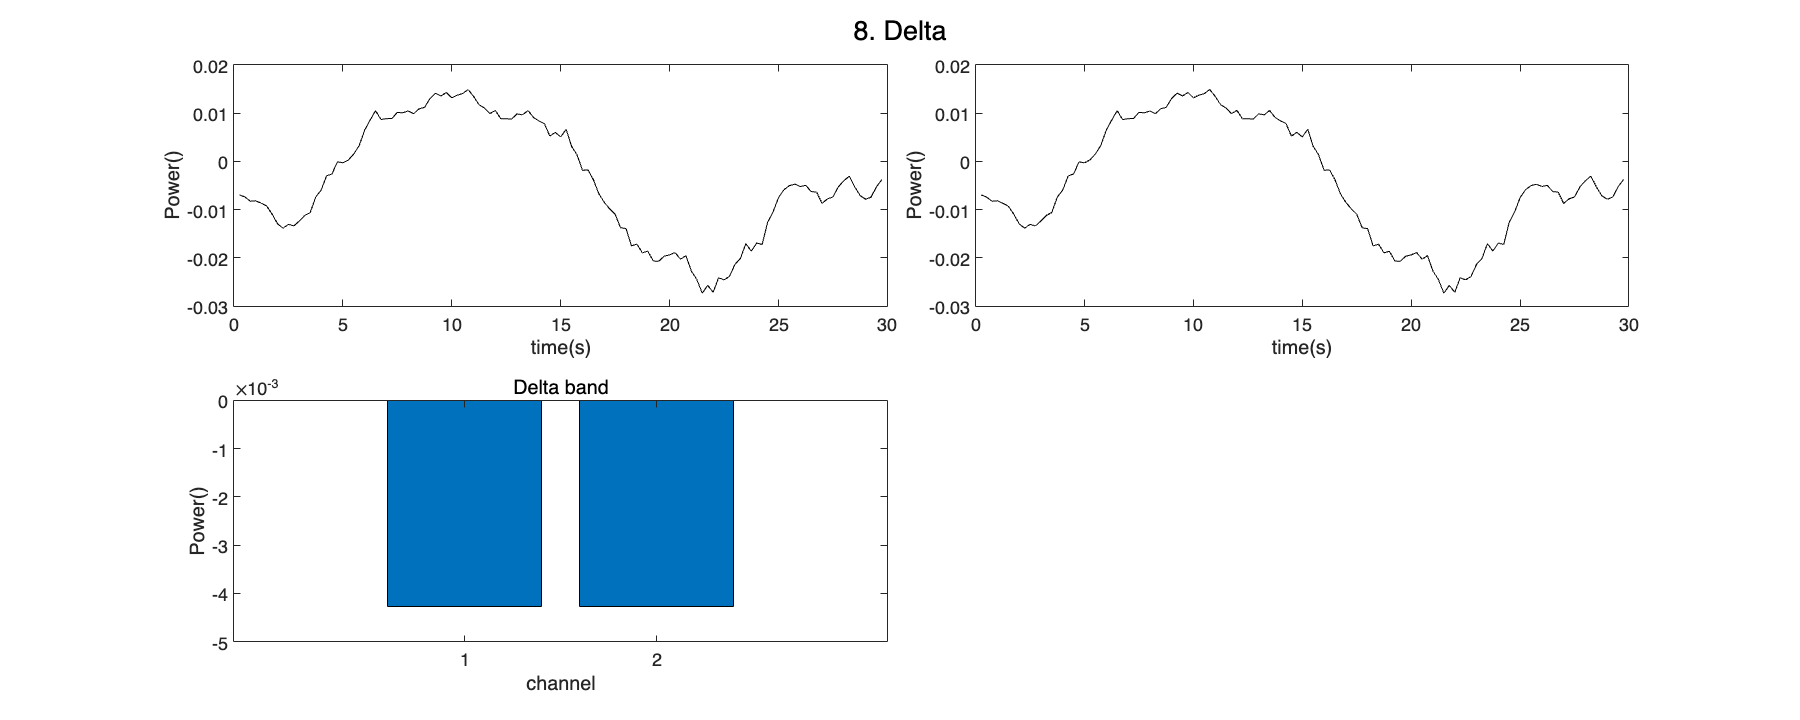

% Frequency 1-3 Hz
Wn3= find(F>1&F<3);
Delta_power =[];
Blurred_1(:,:)=Blurred_save(1,:,:);
Blurred_2(:,:)=Blurred_save(2,:,:);
%Blurred_3(:,:)=Blurred_save(3,:,:);
%Blurred_4(:,:)=Blurred_save(4,:,:);
%Blurred_5(:,:)=Blurred_save(5,:,:);
%Blurred_6(:,:)=Blurred_save(6,:,:);
%Blurred_7(:,:)=Blurred_save(7,:,:);

Delta_power_1=mean(Blurred_1(Wn3,:));
Delta_power_2=mean(Blurred_2(Wn3,:));
%Delta_power_3=mean(Blurred_3(Wn3,:));
%Delta_power_4=mean(Blurred_4(Wn3,:));
%Delta_power_5=mean(Blurred_5(Wn3,:));
%Delta_power_6=mean(Blurred_6(Wn3,:));
%Delta_power_7=mean(Blurred_7(Wn3,:));
Delta_power(1) = mean(Delta_power_1);
Delta_power(2) = mean(Delta_power_2);
%Delta_power(3) = mean(Delta_power_3);
%Delta_power(4) = mean(Delta_power_4);
%Delta_power(5) = mean(Delta_power_5);
%Delta_power(6) = mean(Delta_power_6);
%Delta_power(7) = mean(Delta_power_7);

figure;
%2 * 4 타일을 만든 다음, 한 그래프가 가로로 두 개의 자리를 차지하게 함
% 자리배치:
% 1 2 3 4
% 5 6 7 8

%플롯 자리 정하는 부분만 채널의 개수와 원하는 배치에 맞게 바꿔 주시면 됩니다.
subplot(2,4,[1 2]),plot(T,Delta_power_1,'k');
xlabel('time(s)'), ylabel('Power()')
subplot(2,4,[3 4]),plot(T,Delta_power_2,'k');
xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[5 6]),plot(T,Delta_power_3,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[7 8]),plot(T,Delta_power_4,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[9 10]),plot(T,Delta_power_5,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[11 12]),plot(T,Delta_power_6,'k');
%xlabel('time(s)'), ylabel('Power()')
%subplot(4,4,[13 14]),plot(T,Delta_power_7,'k');
%xlabel('time(s)'), ylabel('Power()')

subplot(2,4,[5 6]),bar(Delta_power);
xlabel('channel'), ylabel('Power()');
%ylim([0 0.008]) % y 범위 적절히 조절
subtitle('Delta band')
sgtitle('8. Delta')